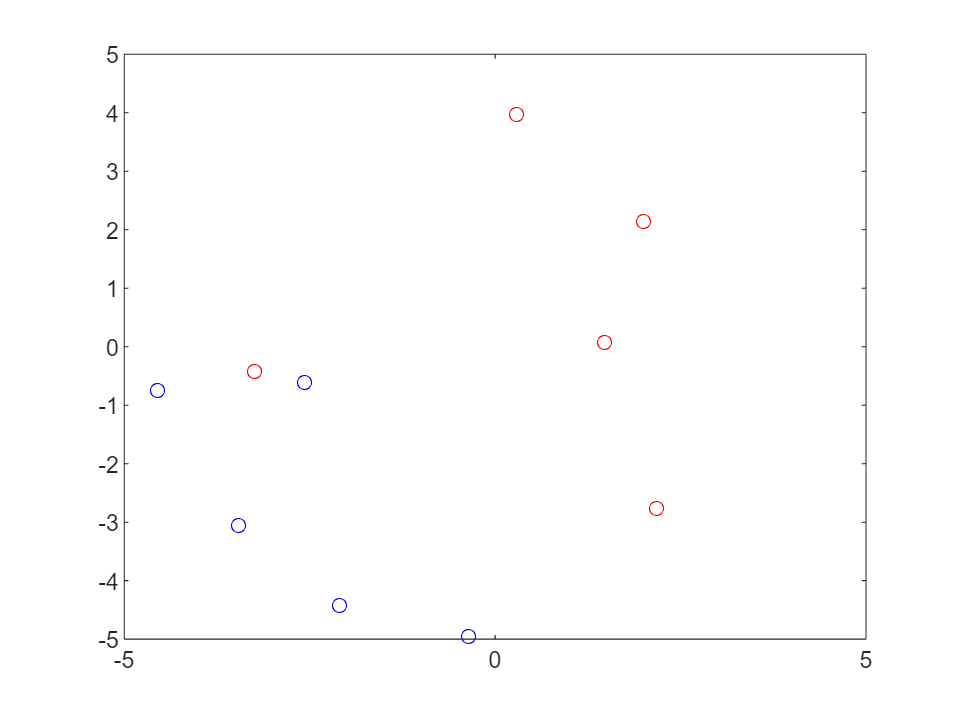

% coverage
% 区域是10m×10m的
clear
l1=-5;
l2=5;
reso=0.1;
a = l1:reso:l2; % 分辨率是1mm
b = l1:reso:l2;
% 设置5个重心
rng(88);% 随机种子
mu = l1 + (l2-l1) *rand(2,5);
figure
plot(mu(1,:),mu(2,:),'ro')
hold on;
% 初始化机器人的位置
p = l1 + (l2-l1)/2 *rand(2,5);
plot(p(1,:),p(2,:),'bo');
axis([l1,l2,l1,l2])

phi = zeros(size(a,2),size(b,2));
for i = 1:size(a,2)
    for j = 1:size(b,2)
        q =[a(i);b(j)];
        phi(i,j)=getphi(q,mu);
    end
end

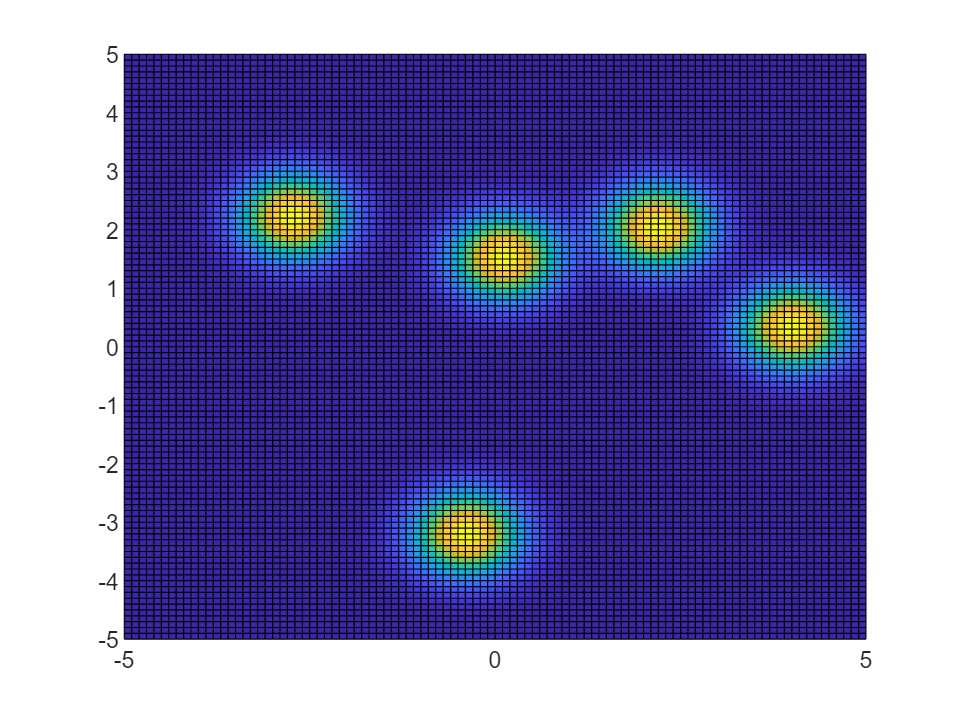

figure
[X,Y]=meshgrid(a,b);
surf(X,Y,phi)
view(2)

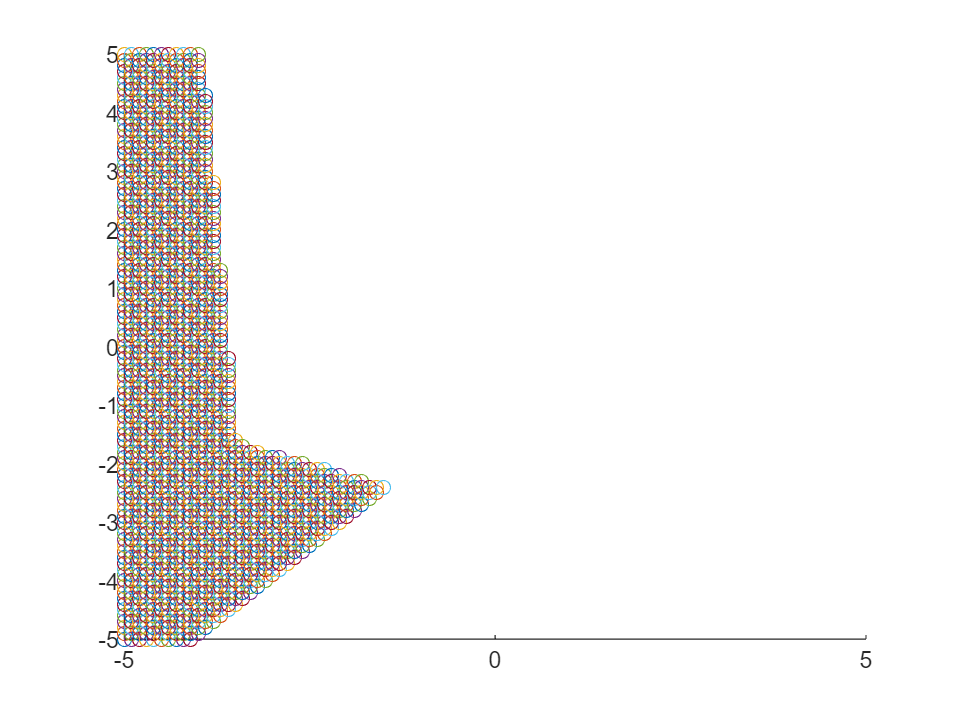

% 迭代
V = zeros(size(a,2),size(b,2),size(p,2));
iter = 100;
col = ['ro','go','bo','po','ko'];
figure
hold on
% for k = 1:iter
    for i = 1:size(a,2)
        for j = 1:size(b,2)
            q =[a(i);b(j)];
            dis = sum((p-q).^2);
            index = find(dis==min(dis));
            V(i,j,index) = phi(i,j);
            plot(a(i),b(j),col(index))
        end
    end

% end

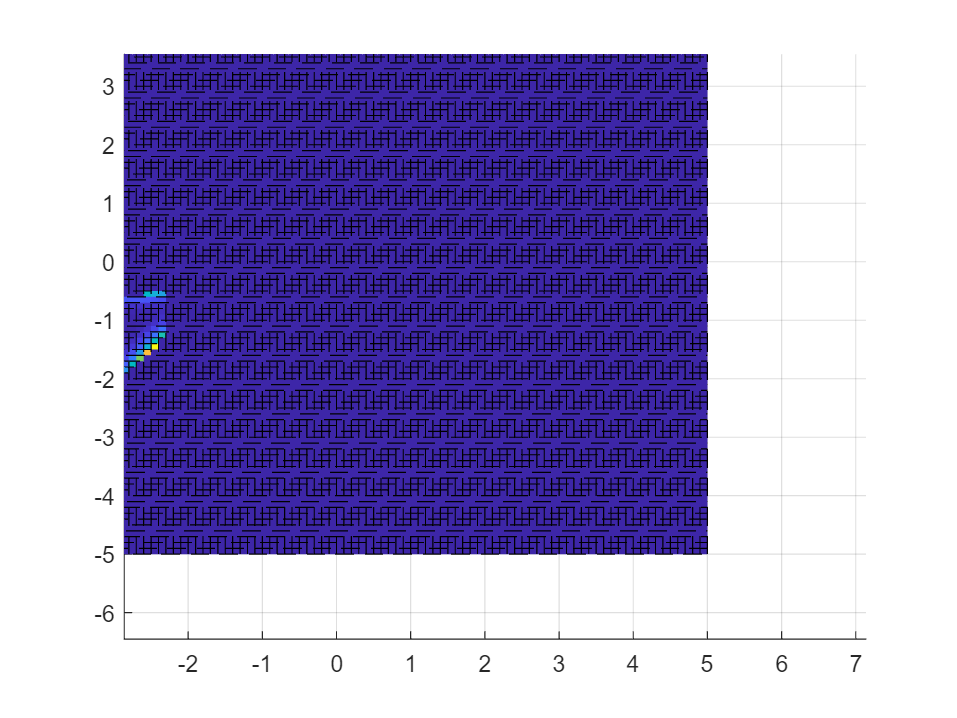


surf(X,Y,V(:,:,5),'LineStyle','--')
view(2)

% mu=[0,0];% 均值向量
% Sigma=[1 0.8;0.8 1];% 协方差矩阵
% [X,Y]=meshgrid(-3:0.1:3,-3:0.1:3);%在XOY面上，产生网格数据
% p=mvnpdf([X(:) Y(:)],mu,Sigma);%求取联合概率密度，相当于Z轴
% p=reshape(p,size(X));%将Z值对应到相应的坐标上
% 
% figure
% set(gcf,'Position',get(gcf,'Position').*[1 1 1.3 1])
% 
% subplot(2,3,[1 2 4 5])
% surf(X,Y,p),axis tight,title('二维正态分布图')
% subplot(2,3,3)
% surf(X,Y,p),view(2),axis tight,title('在XOY面上的投影')
% subplot(2,3,6)
% surf(X,Y,p),view([0 0]),axis tight,title('在XOZ面上的投影')


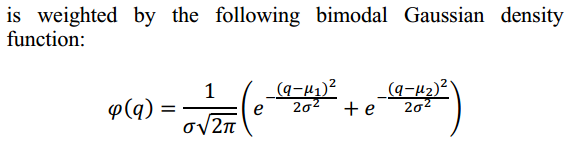

密度函数，有几个重心就有几个μ

function result = getphi(q,mu)
sigma = 0.5;
result = 0;
for i = 1:size(mu,2)
result = result + 1/sigma/sqrt(2*pi)*...
    exp(-norm(q-mu(:,i))^2/2/sigma/sigma);
end
end